# **标量场的等高线演示**

- **生成网格并定义一个函数**

**         与上一小节类似，计算下列函数的标量场等高线及梯度场：**


$$z=\left(a*x+b*y\right)*\exp \left({c*x}^d +{e*y}^f \right)$$


[xx,yy] = meshgrid(-2:.2:2); 

a =-1;
b =-2;
c =-2;
d = 2;
e =-1;
f = 2;
z = (a * xx + b * yy).*exp(c * xx.^d + e * yy.^f); 
fprintf('二元函数为z = (%d*x + %d*y) *exp(%d*x^%d + %d*y^%d)\n', a, b, c, d, e,f);

二元函数为z = (-1*x + -2*y) *exp(-2*x^2 + -1*y^2)


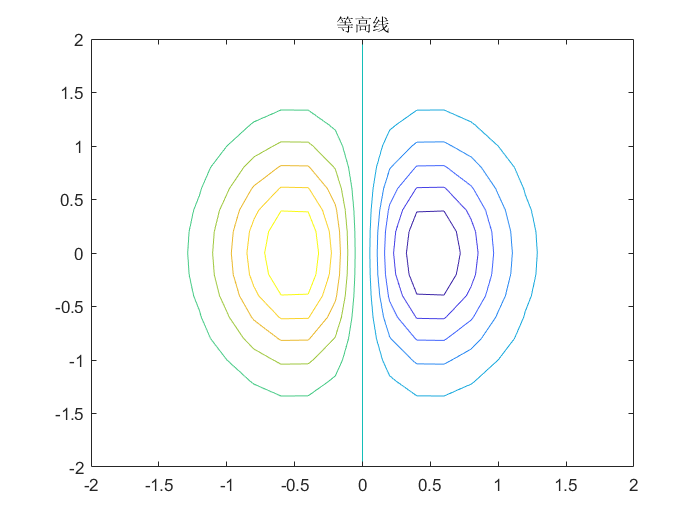

figure;
contour(xx,yy,z) ; % 绘制等高线
title('等高线')
set(gcf,'Visible','on');   	    %强制图片弹出输出

- **使用gradient函数求梯度并使用quiver绘制矢量图**

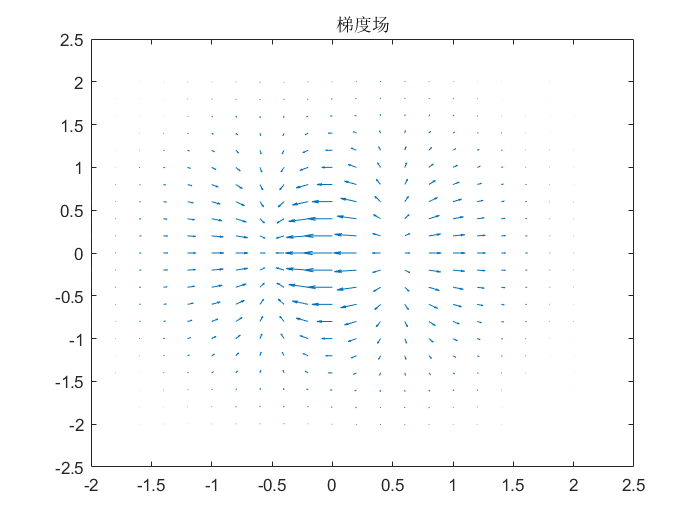

[dx,dy] = gradient(z,0.2,0.2); % 计算曲面上各点处的梯度
figure;
quiver(xx,yy,dx,dy) ; % 绘制梯度场
title('梯度场')
set(gcf,'Visible','on');   	    %强制图片弹出输出

- **将梯度场和标量场绘制在一起**

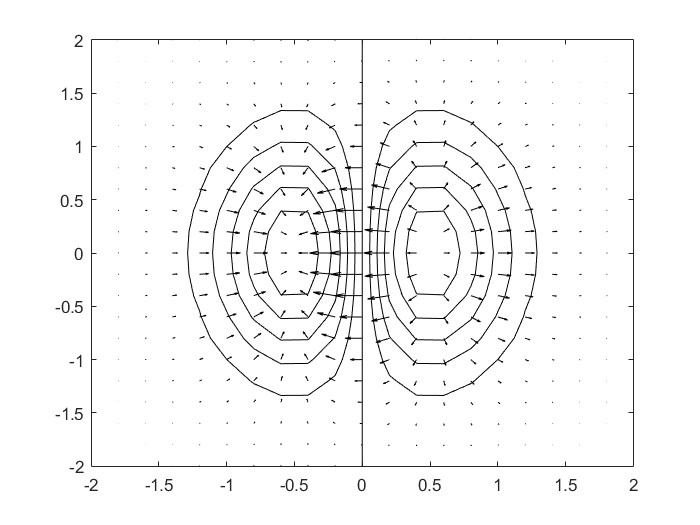

figure;
contour(xx,yy,z);
hold on
quiver(xx,yy,dx,dy) ; 
h = get(gca,'Children'); % 获取当前axes对象的所有子对象的句柄
set(gcf,'Visible','on');   	    %强制图片弹出输出
set(h, 'Color','k');